clc;
clear all;
close all;

% Parámetros del sistema
m1 = 400; % auto
k1 = 30000; 
b1 = 4500;

m2 = 45; % neumático
k2 = 180000;
b2 = 300;

% Definición de TF
% Numerador de la función de transferencia
num = [b1*b2, k1*b2 + k2*b1, k1*k2];  

% Denominador
den = [m1*m2, m1*(b1 + b2) + m2*b1, m1*(k1 + k2) + m2*k1 + b1*b2, k1*b2 + k2*b1, k1*k2];

% Creación de la función de transferencia
T = tf(num, den);
fprintf(' - Función de transferencia: %s\n', evalc('T'));

 - Función de transferencia: 
T =
 
               1.35e06 s^2 + 8.19e08 s + 5.4e09
  -----------------------------------------------------------
  18000 s^4 + 2.122e06 s^3 + 8.67e07 s^2 + 8.19e08 s + 5.4e09
 
Continuous-time transfer function.
Model Properties






%% Análisis de polos
poles = pole(T);
disp('Los polos de la función de transferencia son:');

Los polos de la función de transferencia son:


disp(poles);

 -53.9425 +27.2482i
 -53.9425 -27.2482i
  -5.0158 + 7.5487i
  -5.0158 - 7.5487i



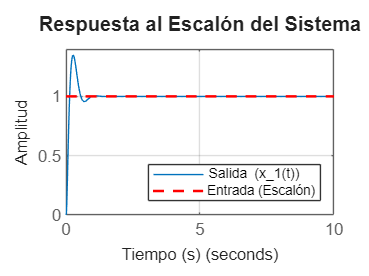


%% Generación de señales de entrada
% Tiempo de simulación
t = 0:0.01:10;  % Vector de tiempo de 0 a 10 segundos con paso de 0.01s

% Señal escalón unitario
u_step = ones(size(t));

% Señal rampa unitaria (pendiente = 1)
u_ramp = t;

%% Simulación de respuestas
% Respuesta al escalón
[y_step, t_step] = step(T, t);

% Respuesta a la rampa 
[y_ramp, t_ramp] = lsim(T, u_ramp, t);

%% Visualización
figure('Color', 'white', 'Position', [100 100 800 600]);

% Gráfica de respuesta al escalón
step(T, t);%función step para simular la respuesta
hold on;
plot(t, u_step, '--r', 'LineWidth', 1.5);  % Señal de entrada (rampa) en rojo
grid on;
title('Respuesta al Escalón del Sistema', 'FontSize', 12);
xlabel('Tiempo (s)', 'FontSize', 10);
ylabel('Amplitud', 'FontSize', 10);
legend({'Salida (x_1(t))', 'Entrada (Escalón)'}, 'Location', 'southeast');

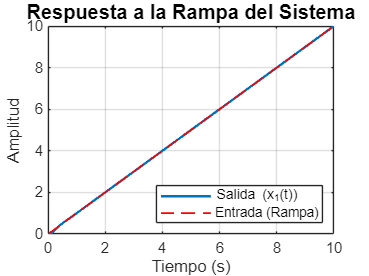



% Gráfica de respuesta a la rampa
figure('Color', 'white', 'Position', [100 100 800 600]);

plot(t_ramp, y_ramp, 'LineWidth', 1.5);
hold on;
plot(t, u_ramp, '--r', 'LineWidth', 1);  % Señal de entrada (rampa) en rojo
grid on;
title('Respuesta a la Rampa del Sistema', 'FontSize', 12);
xlabel('Tiempo (s)', 'FontSize', 10);
ylabel('Amplitud', 'FontSize', 10);
legend({'Salida (x_1(t))', 'Entrada (Rampa)'}, 'Location', 'southeast');

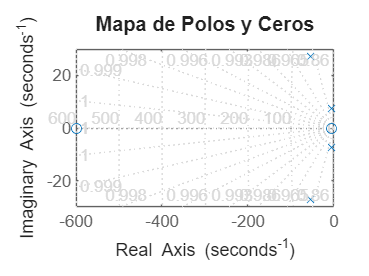


% Diagrama de polos y ceros
figure('Color', 'white', 'Position', [100 100 800 600]);
pzmap(T);
grid on;
title('Mapa de Polos y Ceros', 'FontSize', 12);
set(findall(gcf, 'Type', 'axes'), 'FontName', 'Arial', 'FontWeight', 'bold');